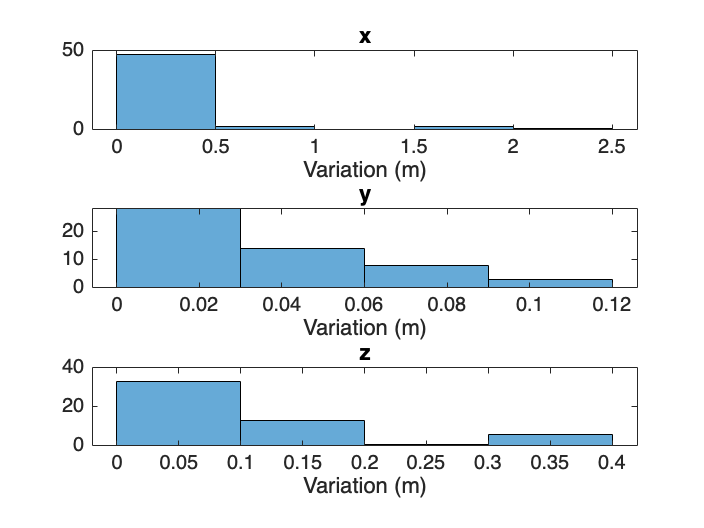

fiducial_variation = readtable('variation_outdoor.txt');

% Plot the fiducial variation histogram for each x,y,z
figure;
subplot(3,1,1)
histogram(fiducial_variation.x)
xlabel('Variation (m)')
title('x')
subplot(3,1,2)
histogram(fiducial_variation.y)
xlabel('Variation (m)')
title('y')
subplot(3,1,3)
histogram(fiducial_variation.z)
xlabel('Variation (m)')
title('z')

% Save figure as png
saveas(gcf, 'fiducial_variation_outdoors.png')

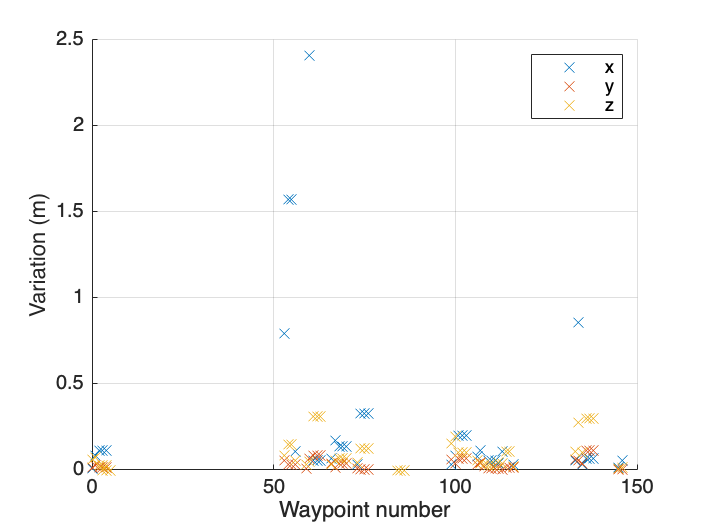


% Plot the fiducial variation against waypoint number, on the same axes
figure;
hold on
grid on
plot(fiducial_variation.waypoint, fiducial_variation.x, 'x')
plot(fiducial_variation.waypoint, fiducial_variation.y, 'x')
plot(fiducial_variation.waypoint, fiducial_variation.z, 'x')
legend('x', 'y', 'z')
xlabel('Waypoint number')
ylabel('Variation (m)')

% Save figure as png
saveas(gcf, 'fiducial_variation_outdoors_waypoint.png')

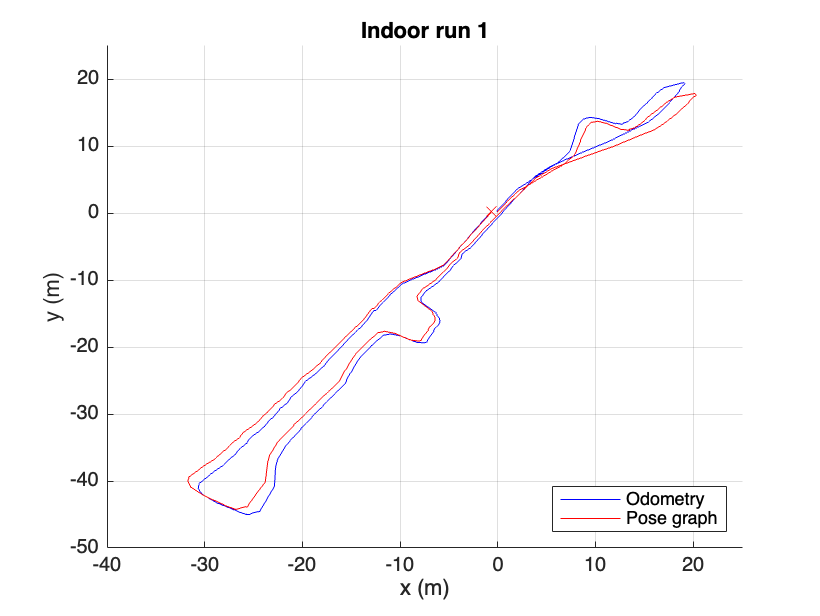

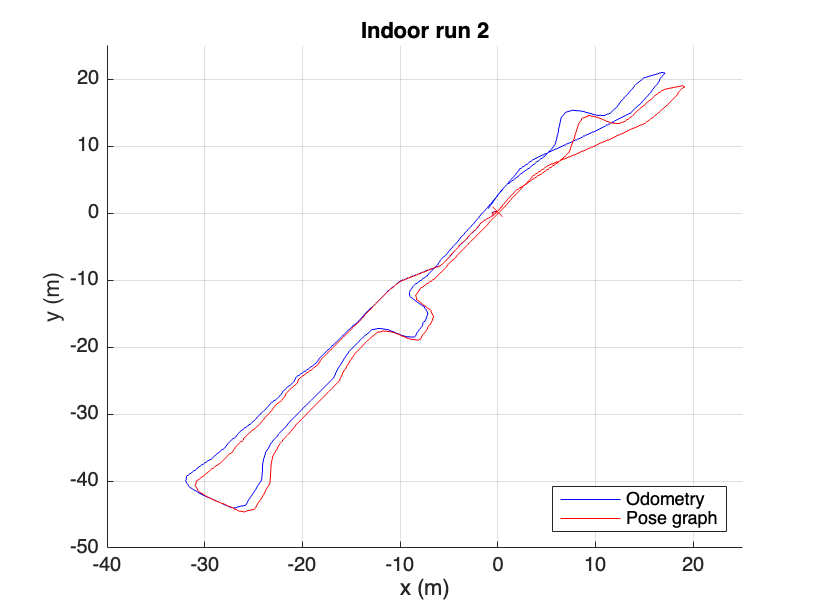

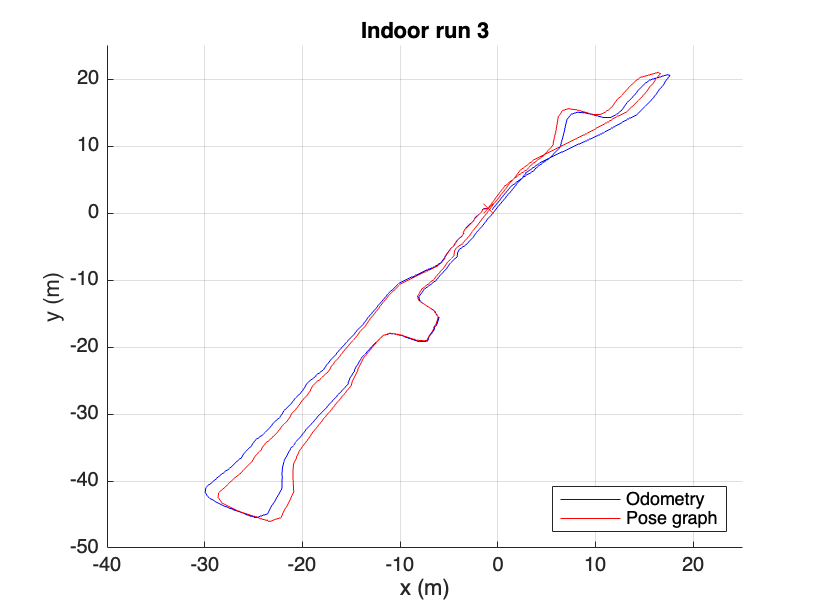

% read in data from file using readtable
for i=1:3
    filename_odom = append('analysis/indoor-odom/walk', string(i), '-poses_odom.txt');
    data_odom = readtable(filename_odom);

    filename_pose = append('analysis/indoor-odom/walk', string(i), '-poses_map.txt');
    data_pose = readtable(filename_pose);

    % subtract initial timestamp value and round to nearest whole number
    initial_timestamp = data_odom.timestamp(1);
    data_odom.timestamp = round(data_odom.timestamp - initial_timestamp);
    initial_timestamp = data_pose.timestamp(1);
    data_pose.timestamp = round(data_pose.timestamp - initial_timestamp);

    % plot x and y position over time
    figure;
    hold on;
    plot(data_odom.x, data_odom.y, 'b-', data_pose.x, data_pose.y, 'r-');
    scatter(data_odom.x(1), data_odom.y(1), 'bx');
    scatter(data_pose.x(1), data_pose.y(1), 'rx');
    title(append('Indoor run ', string(i)));
    xlim([-40,25]);
    ylim([-50,25]);
    xlabel('x (m)');
    ylabel('y (m)');
    grid on;
    legend('Odometry', 'Pose graph', 'Location', 'southeast');

    figname = append('analysis/indoor-walk', string(i), '.png');
    saveas(gcf, figname);
end

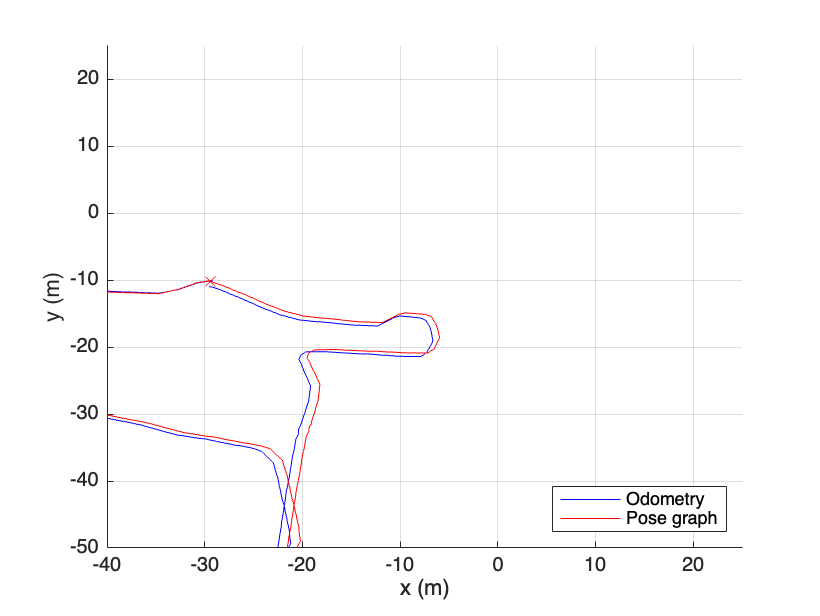

% Outdoor odom
for i=1:1
    filename_odom = append('analysis/outdoor-odom/walk', string(i), '-poses_odom.txt');
    data_odom = readtable(filename_odom);

    filename_pose = append('analysis/outdoor-odom/walk', string(i), '-poses_map.txt');
    data_pose = readtable(filename_pose);

    % subtract initial timestamp value and round to nearest whole number
    initial_timestamp = data_odom.timestamp(1);
    data_odom.timestamp = round(data_odom.timestamp - initial_timestamp);
    initial_timestamp = data_pose.timestamp(1);
    data_pose.timestamp = round(data_pose.timestamp - initial_timestamp);

    % plot x and y position over time
    figure;
    hold on;
    plot(data_odom.x, data_odom.y, 'b-', data_pose.x, data_pose.y, 'r-');
    scatter(data_odom.x(1), data_odom.y(1), 'bx');
    scatter(data_pose.x(1), data_pose.y(1), 'rx');
    xlabel('x (m)');
    ylabel('y (m)');
    grid on;
    legend('Odometry', 'Pose graph', 'Location', 'southeast');

    figname = append('analysis/outdoor-walk', string(i), '.png');
    saveas(gcf, figname);
end